# Načrtovanje PID-regulatorjev s pomočjo metod Ziegler-Nichols

## Naloga 1

Realizirajte vse štiri sisteme.

### Sistem 1

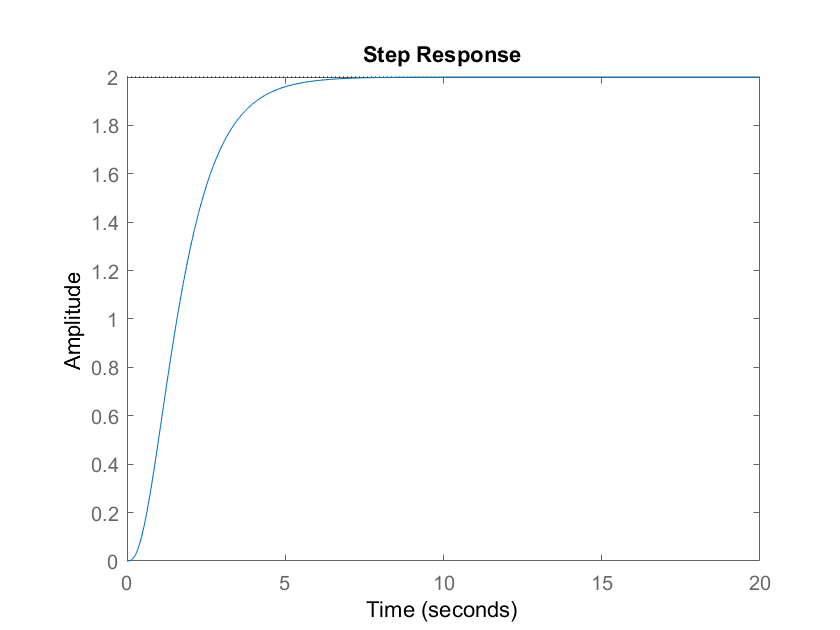

s = tf('s');
G1 = 12/(s + 1)/(s + 2)/(s + 3);
step(G1, 20)

### Sistem 2

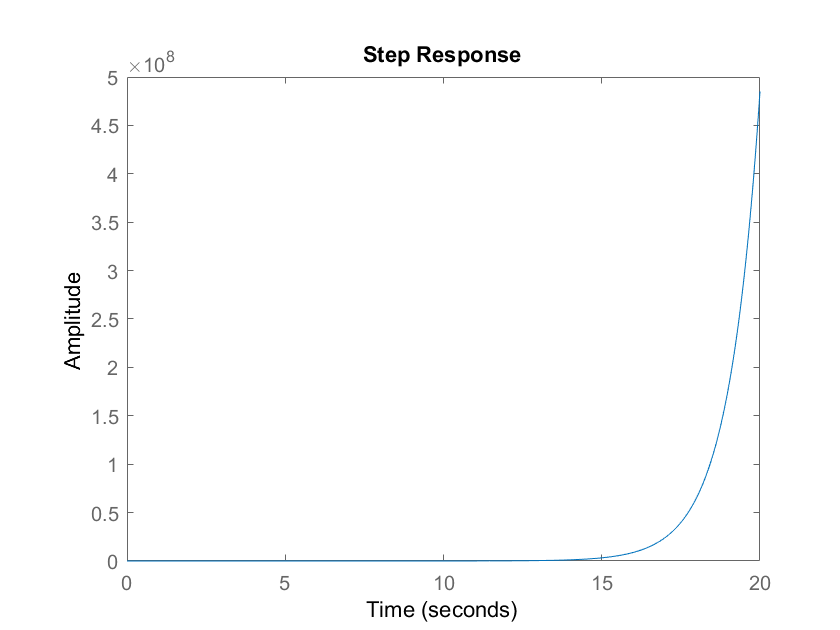

s = tf('s');
G2 = 12/(s - 1)/(s + 2)/(s + 3);
step(G2, 20)

### Sistem 3

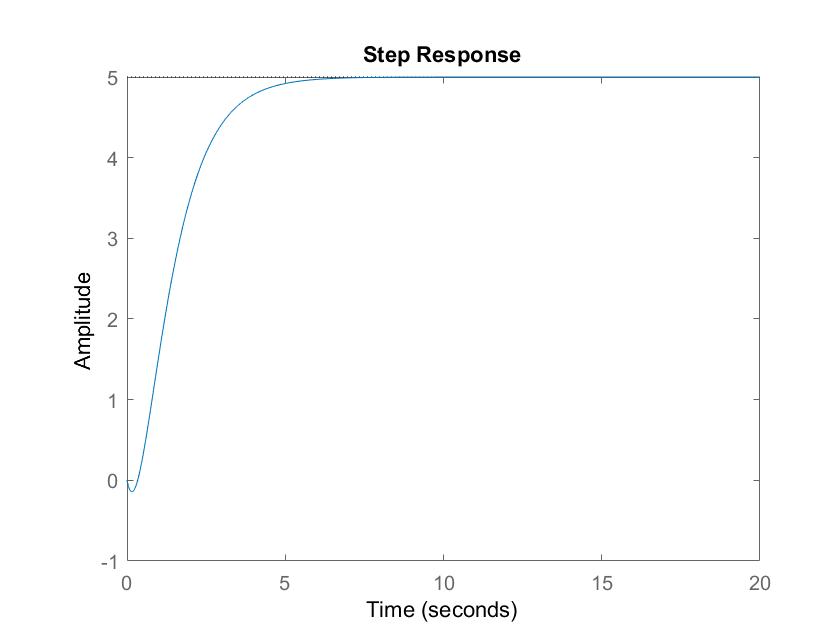

s = tf('s');
G3 = 2*(5 - s)/(s + 1)/(s + 2);
step(G3, 20)

### Sistem 4

s = tf('s');
G4 = 2*(5 - s)/(s + 1)/(s - 1);
step(G2, 20)

## Naloga 2

Dolocite ojacenje Ks, cas zakasnitve Tza in cas izravnave Tiz teh sistemov

Pomagajte si z risanjem crte (v meniju okna Figure imate na voljo Insert ! Line). Na osnovi ocenjenih

parametrov in tabele 1 nacrtajte PID-regulator za obravnavane stabilne procese. Preverite

odziv reguliranega procesa na enotino stopnico.

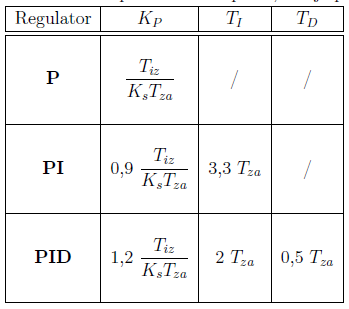

%s = tf('s');
%G4 = 2*(5 - s)/(s + 1)/(s - 1);
%K =1
%G_4 = K*G4;
%[Y4, T4] = step(G_4/(1 + G_4), 10);
%plot(T4, Y4)

### Sistem 1

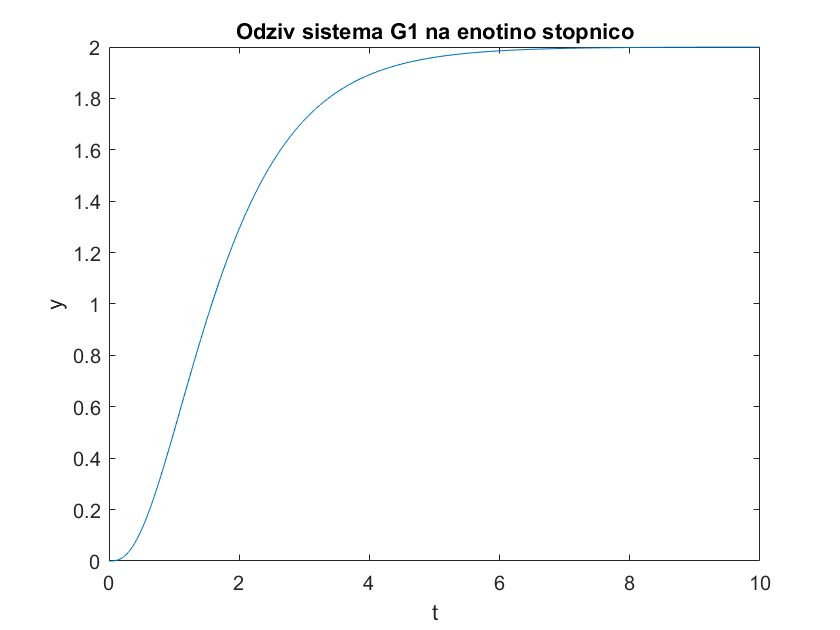

[y, t] = step(G1, 10);
plot(t, y);
title('Odziv sistema G1 na enotino stopnico'); xlabel('t'); ylabel('y');

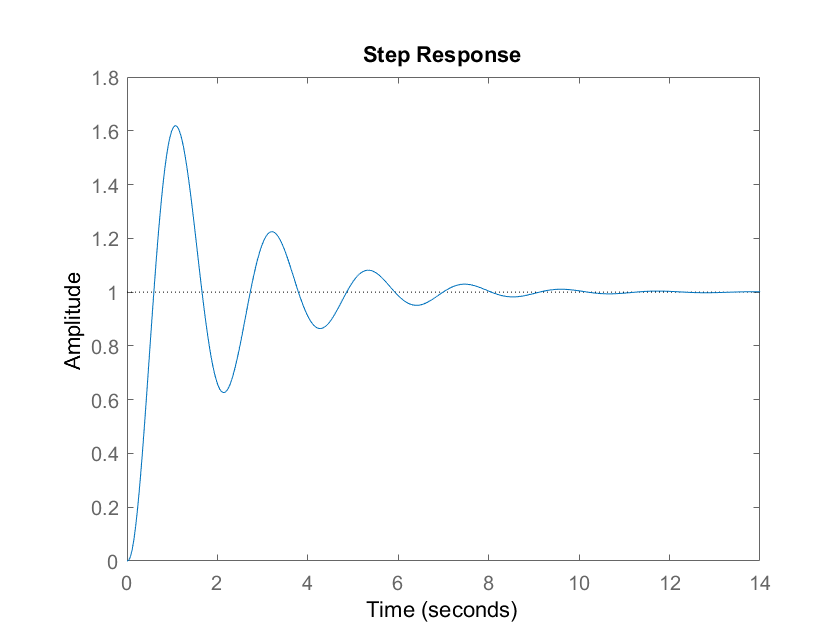

Ks = 2;
Tza = 0.4;
Tiz = 2.4;
Kp = 1.2*Tiz/Ks/Tza;
Ti = 2*Tza;
Td = 0.5*Tza;
Tf = 0.1* Td;

Gpid = Kp *(1 + 1/( Ti*s) + Td*s/(Tf*s + 1));
Go = minreal (G1*Gpid);
step(minreal(Go/(1 + Go)));

### Sistem 2

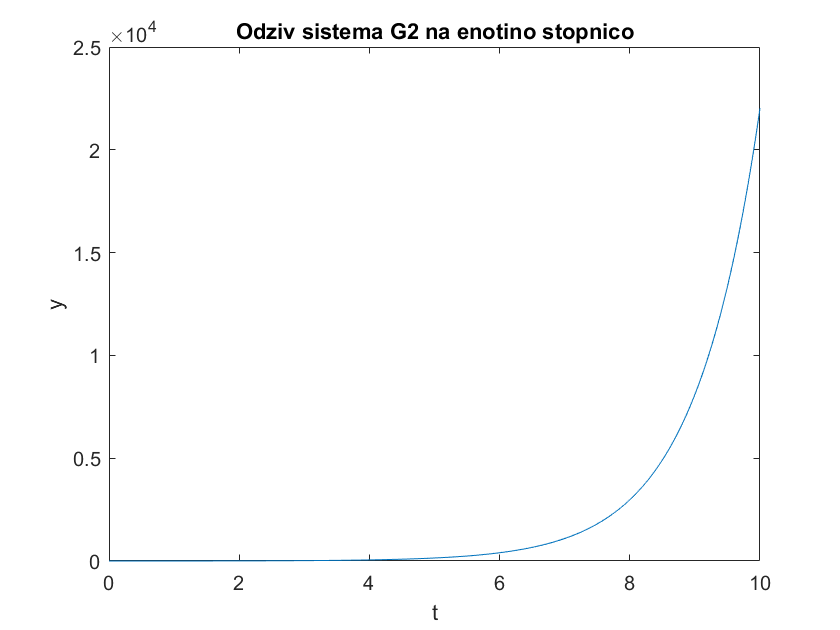

[y, t] = step(G2, 10);
plot(t, y);
title('Odziv sistema G2 na enotino stopnico'); xlabel('t'); ylabel('y');

%Metoda po Ziegler-Nicholsu za nacrtovanje regulatorjev PID 
%velja za stabilne procese!

### Sistem 3

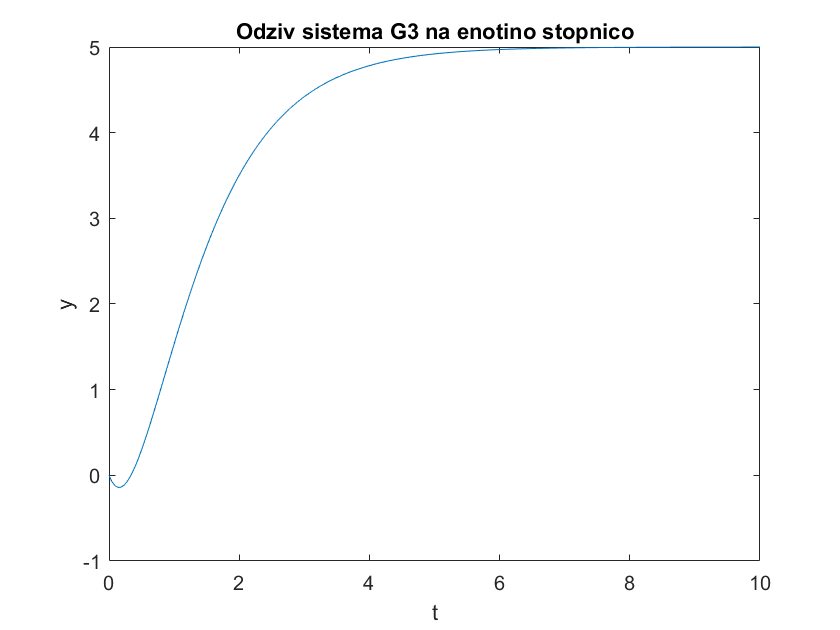

[y, t] = step(G3, 10);
plot(t, y);
title('Odziv sistema G3 na enotino stopnico'); xlabel('t'); ylabel('y');

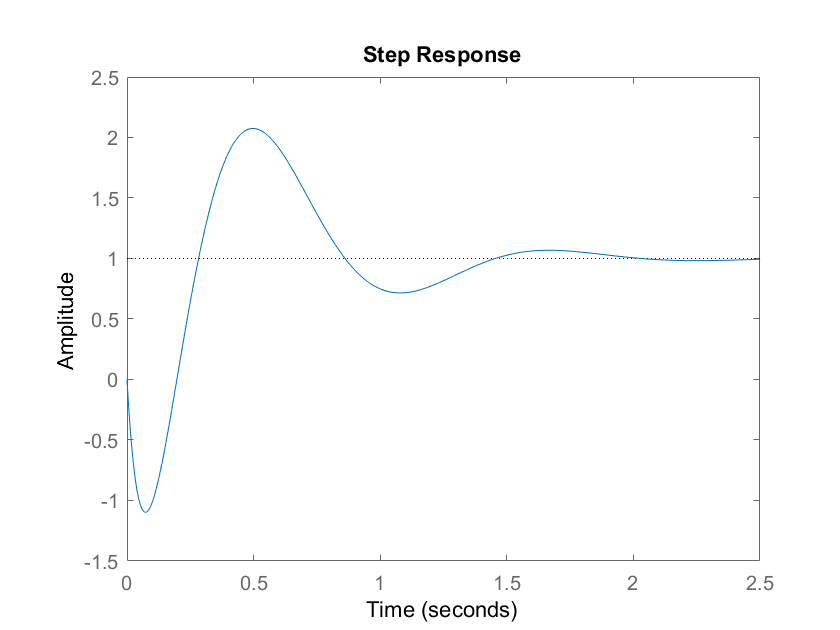

Ks = 5;
Tza = 0.35;
Tiz = 2.45;
Kp = 1.2*Tiz/Ks/Tza;
Ti = 2*Tza;
Td = 0.5*Tza;
Tf = 0.1* Td;

Gpid = Kp *(1 + 1/( Ti*s) + Td*s/(Tf*s + 1));
Go = minreal (G3*Gpid);
step(minreal(Go/(1 + Go)));

### Sistem 4

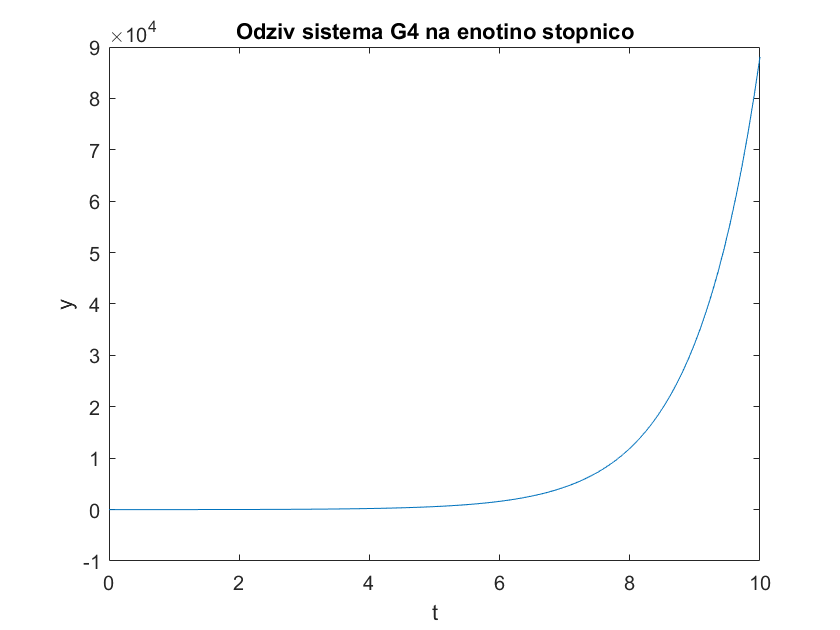

[y, t] = step(G4, 10);
plot(t, y);
title('Odziv sistema G4 na enotino stopnico'); xlabel('t'); ylabel('y');

%Metoda po Ziegler-Nicholsu za nacrtovanje regulatorjev PID 
%velja za stabilne procese!

## Naloga 3

Analizirali bomo stabilnost obravnavanih štirih sistemov, ki so regulirani s P-regulatorjem

in negativno enotino povratno zanko. S pomocjo Routhove sheme dolocite, za katere

vrednosti ojacenj P - regulatorjev so obravnavani zaprtozancni sistemi stabilni. Rezultate

podajte v obliki neenacb.

### Sistem 1

-1/2  < K < 5  Sistem je stabilen

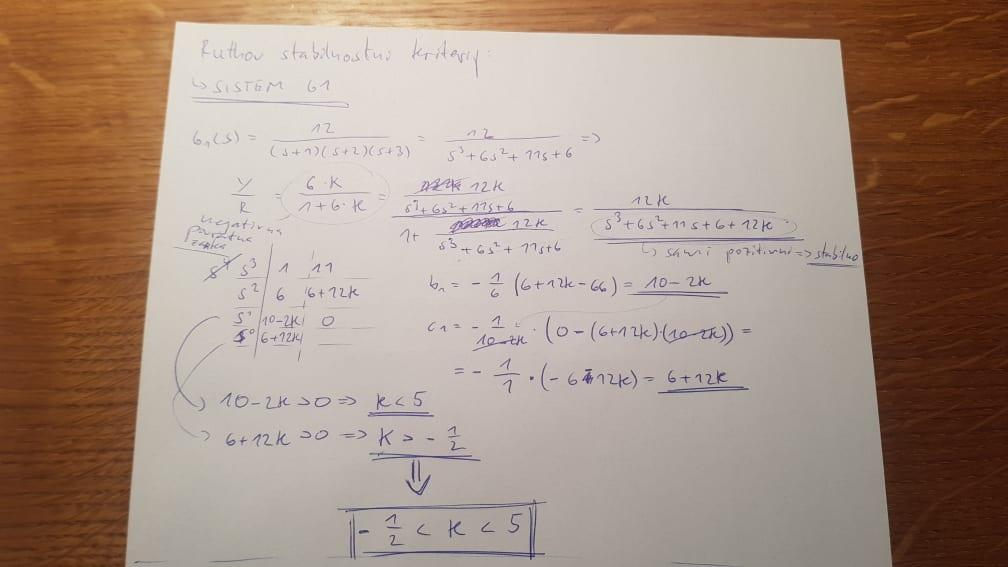

### Sistem 2

1/2 < K < 5/6 Sistem je mejno stabilen - kar nam kaže zelo majhen interval rešitve!

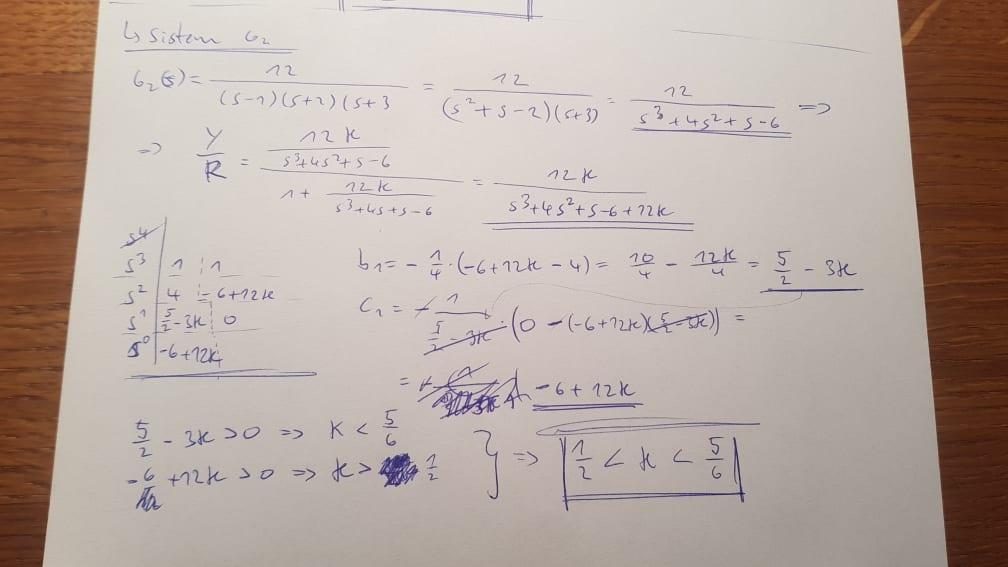

### Sistem 3

-1/5 < K < 3/2  Sistem je stabilen

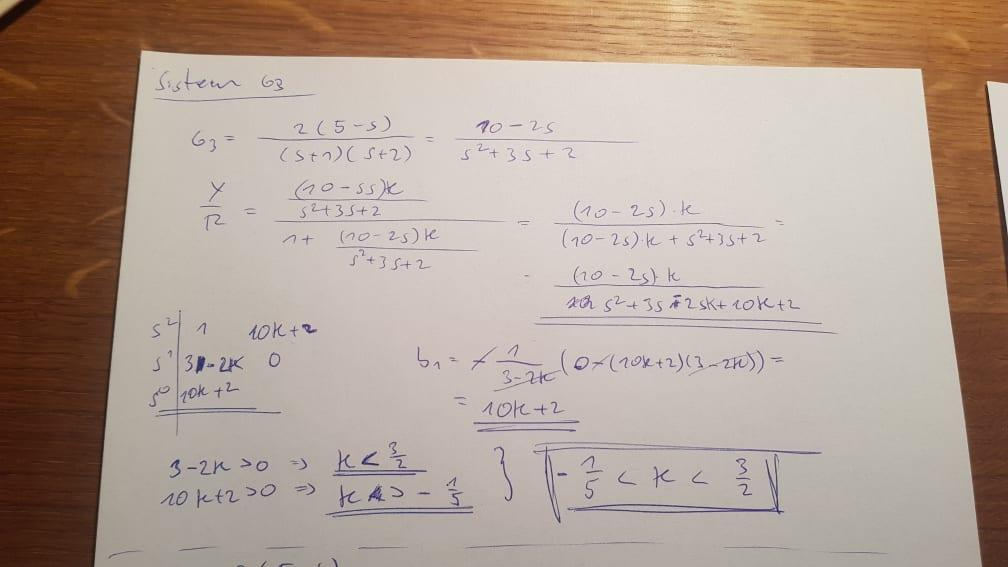

### Sistem 4

Prazna množica -->  K = {}  Iz tega tudi vidimo da je sistem popolnoma nestabilen!

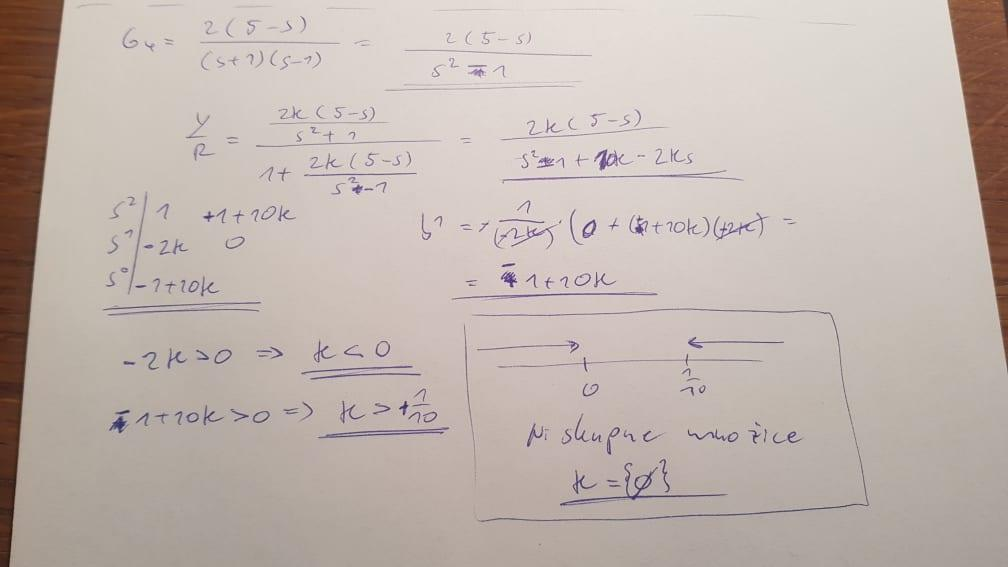

## Naloga 4

Druga metoda po Ziegler-Nicholsu za nacrtovanje regulatorjev PID temelji na nihajnem

preizkusu. Tega opravimo tako, da v zanko skupaj s procesom vkljucimo spremenljivo

ojacenje (P-regulator). Temu spreminjamo ojacenje od 0 do tocke, ko proces zaniha. Ker

so poli celotnega zaprtozancnega sistema pri ojacenju regulatorja 0 enaki polom procesa

(Zakaj?), je tudi ta metoda primerna le za stabilne sisteme. S pomocjo funkcij rlocus

in rlocfind dolocite kriticno ojacenje Kkr in periodo nihanja Tkr. Ta dva podatka lahko

seveda dolocimo tudi pri nekaterih nestabilnih sistemih. Na osnovi ocenjenih parametrov

in tabele 2 nacrtajte PID-regulator za obravnavane procese. Preverite odziv reguliranega

procesa na enotino stopnico.

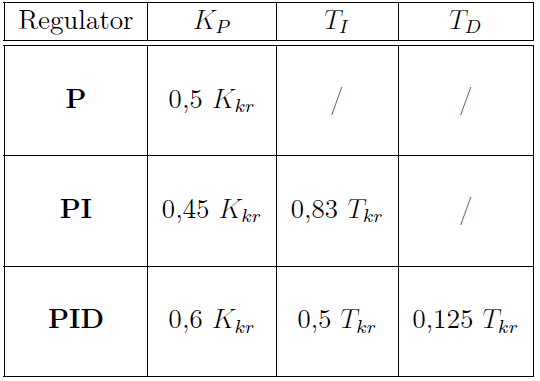

### Sistem 1

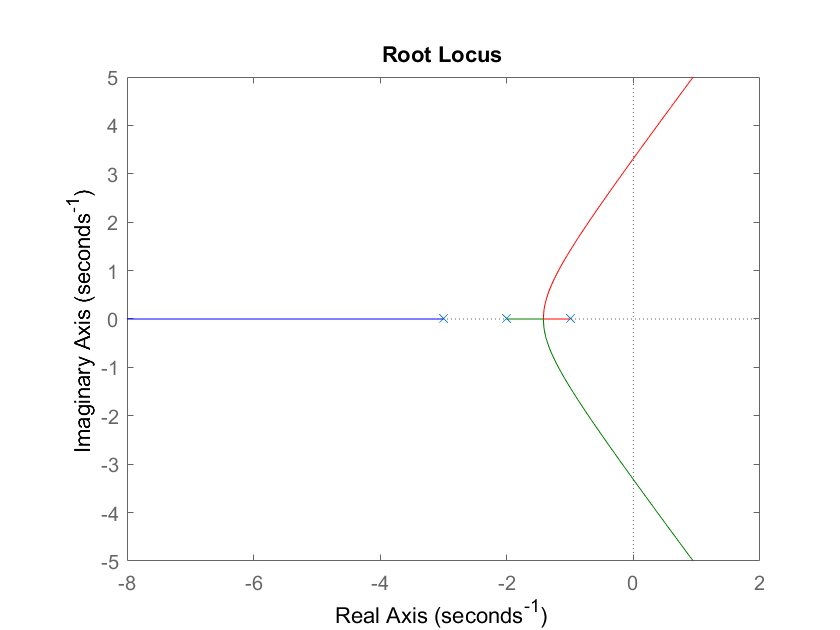

s = tf('s'); %laplacov operator
rlocus(G1);  %Narise DLK prenosne fukncije - vidimo kje funckija seka ordinato - iz tega dobimo krozno frekvenco

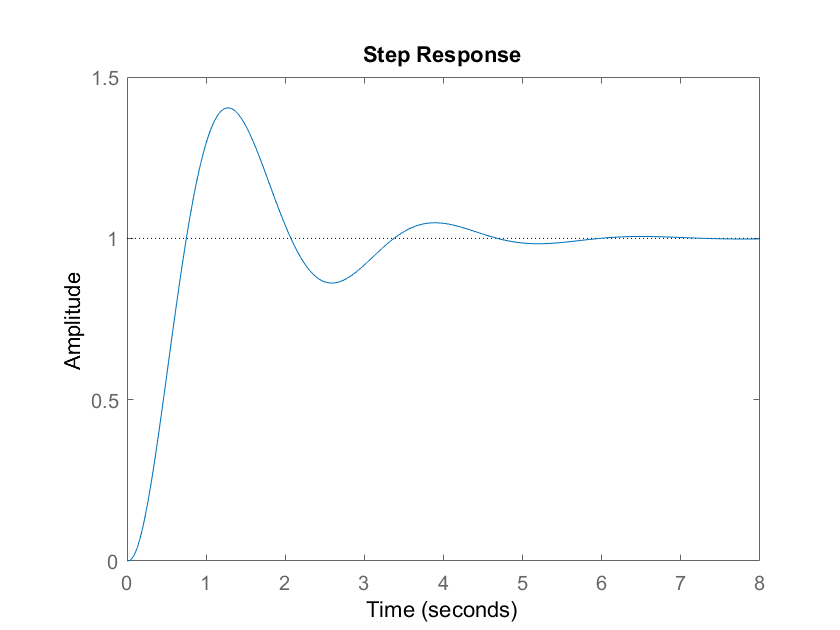

%[K, poles] = rlocfind(G1);  % Ta nam ponudi da na grafu(ki nam ga poda
%rlocus)oznacimo tocko da lahko ocitamo vrednosti
Wn = 3.26; %odcitana vrednost krozne frekvende, pri kateri se pojavi kriticno dusenje
Kkr = 4.7704; %odcitano ojacanje pri kateri se pojavi kriticno dusenje
Tkr = 2*pi/Wn; %izracunan csovna konstanta itd ostale - za PID regulator
Kp = 0.5 * Kkr;
Ti = 0.5 * Tkr;
Td = 0.125*Tkr;
Tf = 0.1*Td;


Gpid = Kp*(1 + 1/(Ti*s) + Td*s/(Tf*s + 1)); % Izracunamo prenosno funkcijo za pid regulator
Go = minreal(G1*Gpid); 
step(minreal(Go/(1 + Go))); %prikazemo odziv regulatorja na enotino stopnico 

Vidimo da je sistem stabilen - potem ko smo na vhod dali enotino stopnico, se je sistem dokaj hitro umiril na konstantni vrednosti 1.

### Sistem 2

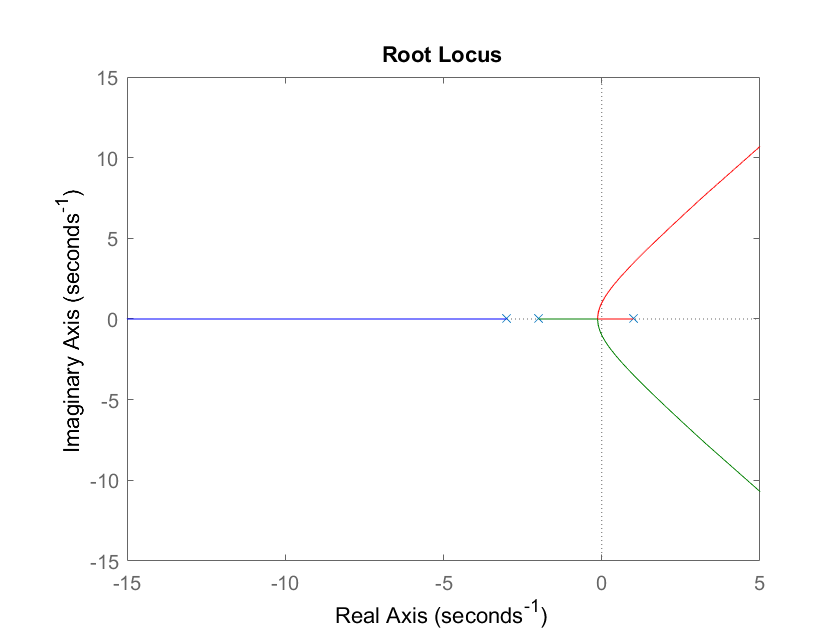

s = tf('s');
rlocus(G2);

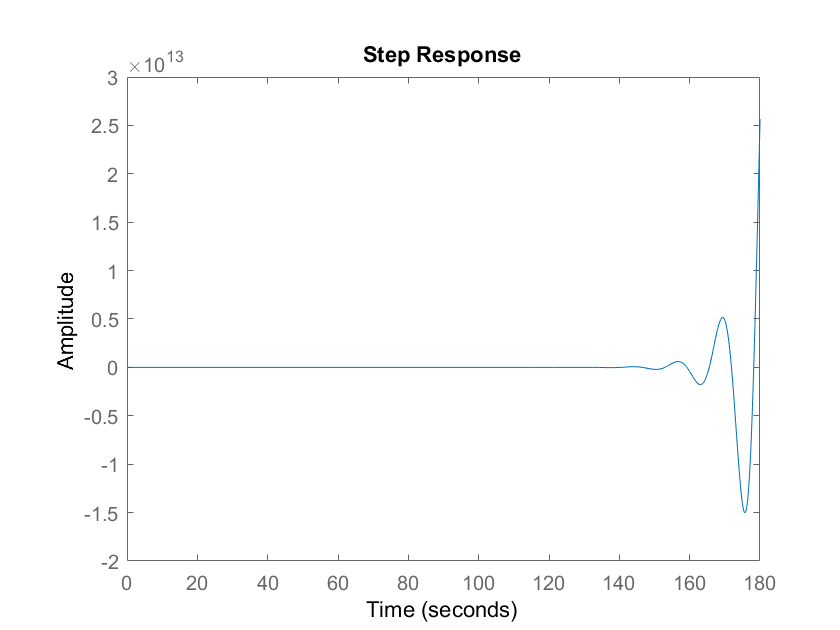

%[K, poles] = rlocfind(G2)
Wn = 1.0194; %odcitano
Kkr = 0.8473; %odcitano
Tkr = 2*pi/Wn; %izracunano
Kp = 0.5 * Kkr;
Ti = 0.5 * Tkr;
Td = 0.125*Tkr;
Tf = 0.1*Td;


Gpid = Kp*(1 + 1/(Ti*s) + Td*s/(Tf*s + 1));
Go = minreal(G2*Gpid);
step(minreal(Go/(1 + Go)));

Vidimo da drugi sistem ni (je zelo pogojno - mogoče z manjšim ojačanjem pride do stabilnosti) stabilen, ko smo na vhod postavili enotino stopnico, se je nekaj časa "zadrževal" nato pa kar naenkrat "izbruhnil" in so šle vrednosti amplitude proti neskončnosti. Ko smo gledali na prejšnem grafu, smo videli da je mejno stabilen - to tukaj dokončno lahko potrdimo. 

### Sistem 3

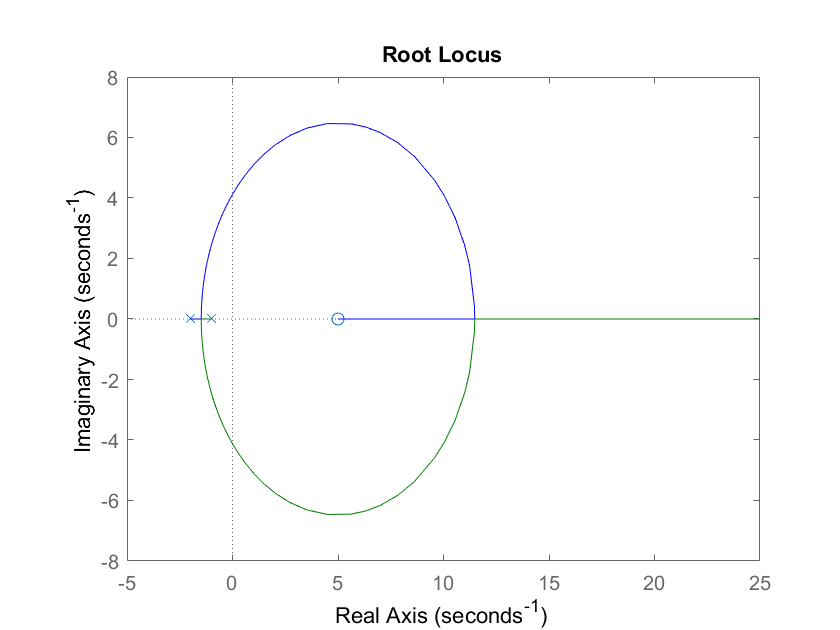

s = tf('s');
rlocus(G3);

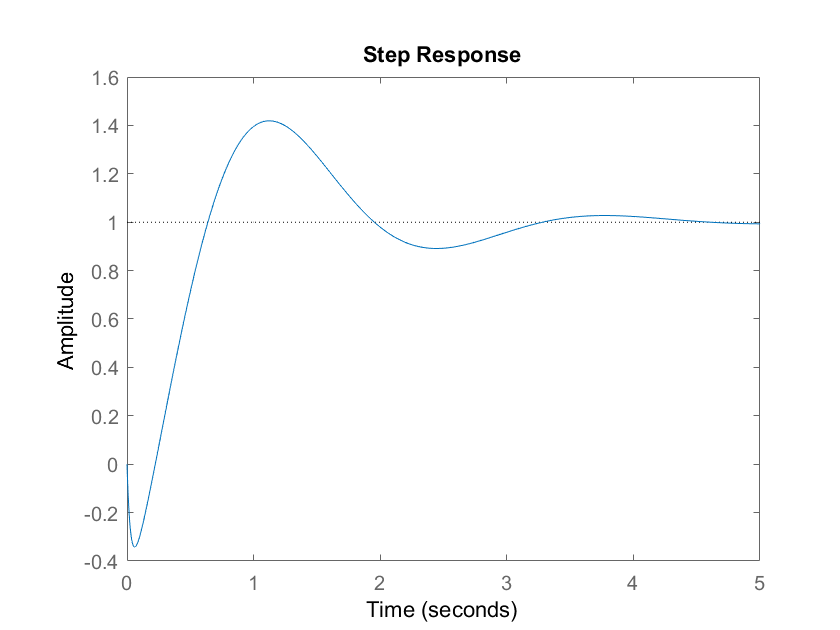

%[K, poles] = rlocfind(G3);
Wn = 4.1383; %odcitano
Kkr = 1.5126; %odcitano
Tkr = 2*pi/Wn; %izracunano
Kp = 0.5 * Kkr;
Ti = 0.5 * Tkr;
Td = 0.125*Tkr;
Tf = 0.1*Td;


Gpid = Kp*(1 + 1/(Ti*s) + Td*s/(Tf*s + 1));
Go = minreal(G3*Gpid);
step(minreal(Go/(1 + Go)));

Za 3. sistem lahko rečemo da je stabilen, malo bolj zaniha kot je 1. sistem vendar se kaj kmalu umiri in se ustali na amplitudi 1.

### Sistem 4

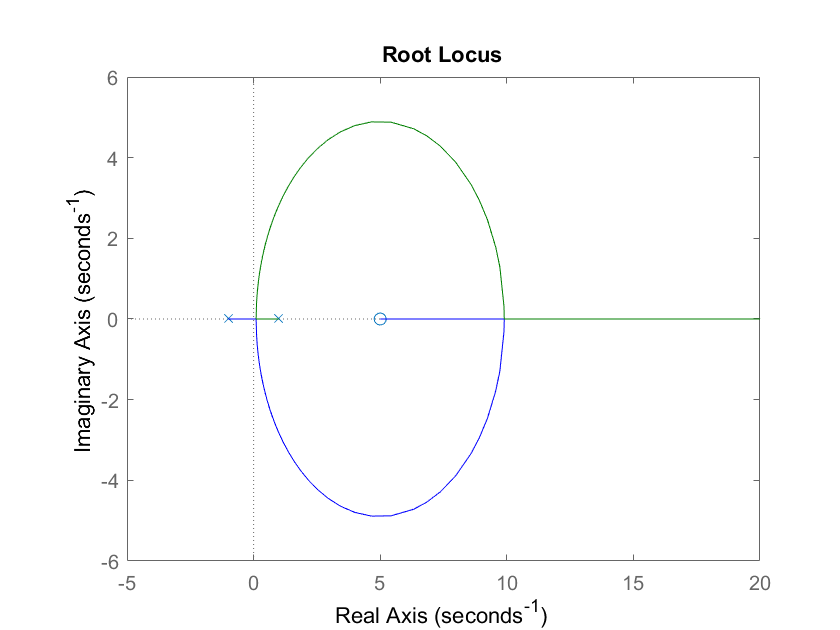

s = tf('s');
rlocus(G4);

%[K, poles] = rlocfind(G4);
Wn = 0; %odcitano
Kkr = 0; %odcitano
Tkr = 2*pi/Wn; %izracunano
Kp = 0.5 * Kkr;
Ti = 0.5 * Tkr;
Td = 0.125*Tkr;
Tf = 0.1*Td;


Gpid = Kp*(1 + 1/(Ti*s) + Td*s/(Tf*s + 1));
Go = minreal(G4*Gpid);
%step(minreal(Go/(1 + Go)));

Vidimo da je četrtki sistem iz zadnjega grafa popolnoma nestabilen, tako da tudi ne moremo določiti korenov, pri katerih naj bi bil sistem stabilen - točke pri kateri naša funkcija seka ordinatno os.